N = 10;

A = [1 Ts; 0 1];
B = [0; Ts];

mat = zeros(2, N);

for i = 1:N
    mat(:,i) = (A^(i-1))*B;
end

AN = A^N;

% Reference -> step response
xr = ones(N, 1);

% initial setting of u vector
u = zeros(N, 1); 

% "learning rate" of u
delta_u = 1;

% initial x 
x0 = [0; 0];

u = zeros(N, 1);
for i = 1:100
    x = find_x(u, AN, mat, N, x0);
    for j = 1:N
        %grd(mat, j, u, x, xr, N)
        u(j) = u(j) - 0.5*grd(mat, j, u, x, xr, N);
    end
end

u

u =          0
    0.1000
    0.1999
    0.2999
    0.3999
    0.4999
    0.5998
    0.6998
    0.7998
    0.8998


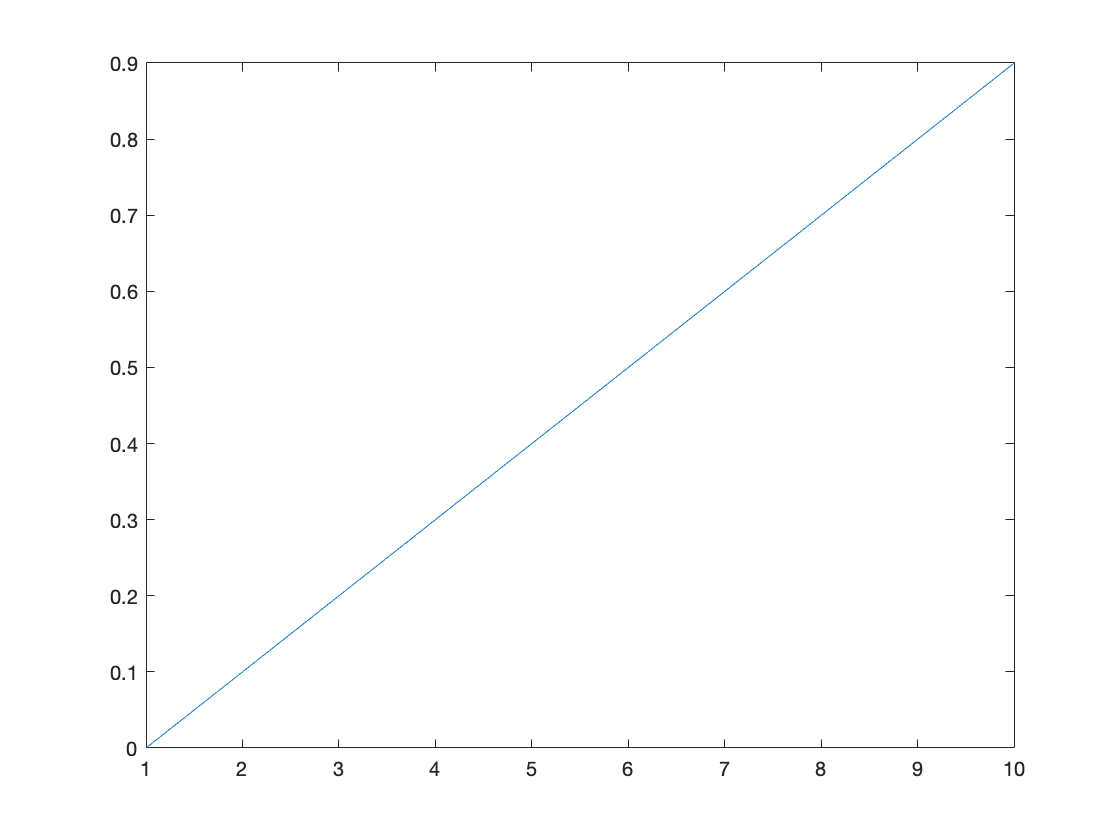

plot(u)

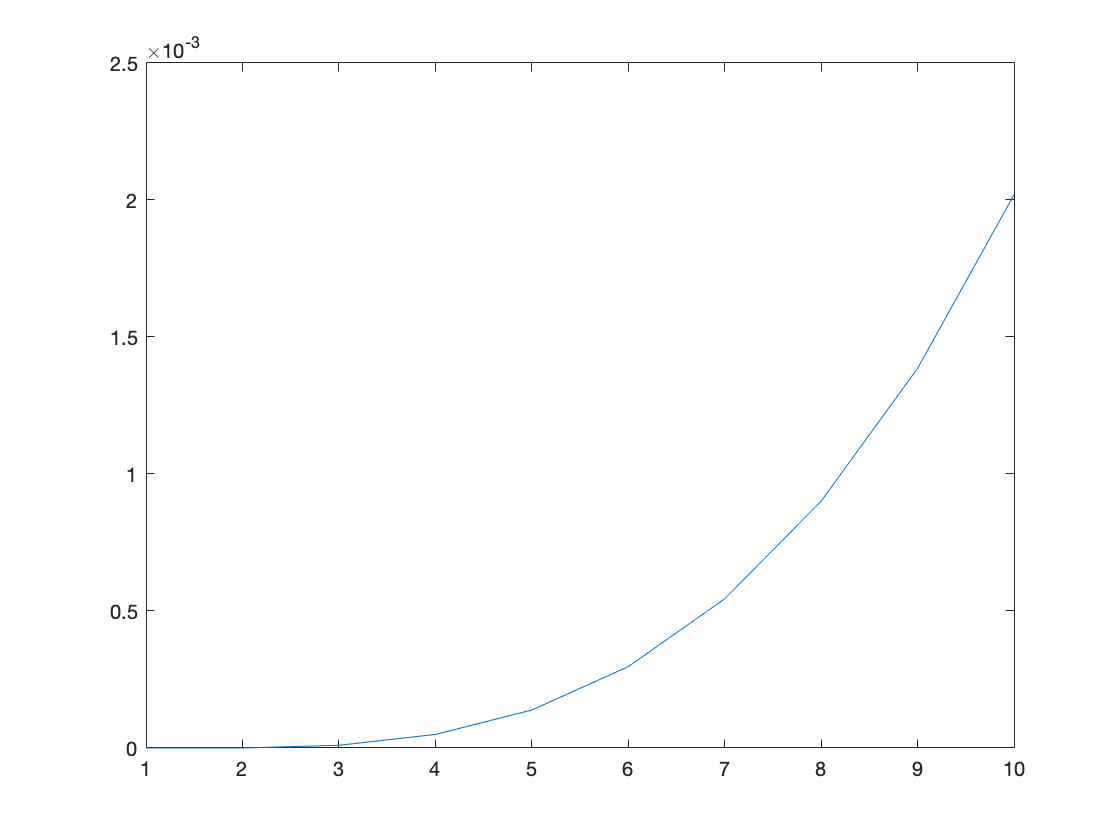

plot(x)

function x_vector = find_x(u, A, mat, N, x0)
    x_vector = zeros(N, 1);
    for i = 1:N-1
        x_vector(i+1) = [1 0]*(A^(i)*x0 + mat(:, 1:i)*u(1:i));
    end
    x_vector(1) = x0(1);
end

function grad = grd(mat, k, u, x, xr, N)
    grad = 0*2*u(k) - 2*[1,0]*mat(:,k)*ones(1, N)*(xr-x);
end